clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Question 1

Gs = 1/(s*(s+2)*(s+3)*(s+6))


Gs =
 
               1
  ----------------------------
  s^4 + 11 s^3 + 36 s^2 + 36 s
 
Continuous-time transfer function.
Model Properties


Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


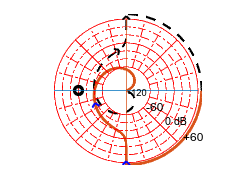

nyqlog(Gs)

Ts = Gs / (1+Gs)


Ts =
 
                        s^4 + 11 s^3 + 36 s^2 + 36 s
  ------------------------------------------------------------------------
  s^8 + 22 s^7 + 193 s^6 + 864 s^5 + 2089 s^4 + 2603 s^3 + 1332 s^2 + 36 s
 
Continuous-time transfer function.
Model Properties


p = pole(Ts)

p =          0
   -6.0000
   -5.9860
   -3.1010
   -3.0000
   -2.0000
   -1.8844
   -0.0286


Question 2

clear;
s = tf('s');

Gs = 20 / (s*(s+1));
Hs = (s+3)/(s+4);
GsHs = Gs*Hs


GsHs =
 
      20 s + 60
  -----------------
  s^3 + 5 s^2 + 4 s
 
Continuous-time transfer function.
Model Properties


Number of poles in RHP of open-loop system: 0
Number of net encirclements around the -1 point:   0
=> Number of poles in RHP of closed-loop system:   0
and no closed-loop poles on Im-axis
=> Closed-loop-system is asymptotically stable


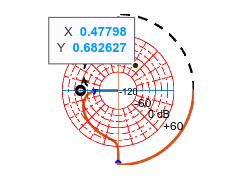


nyqlog(GsHs)

Ts = Gs / (1+GsHs)


Ts =
 
        20 s^3 + 100 s^2 + 80 s
  ------------------------------------
  s^5 + 6 s^4 + 29 s^3 + 84 s^2 + 60 s
 
Continuous-time transfer function.
Model Properties


p = pole(Ts)

p =    0.0000 + 0.0000i
  -0.8646 + 4.1948i
  -0.8646 - 4.1948i
  -3.2708 + 0.0000i
  -1.0000 + 0.0000i


Question 3

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs = 1/((s+2))


Gs =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


Hs = 1/((s+4)*(s+6))


Hs =
 
         1
  ---------------
  s^2 + 10 s + 24
 
Continuous-time transfer function.
Model Properties


GsHs = Gs*Hs


GsHs =
 
             1
  ------------------------
  s^3 + 12 s^2 + 44 s + 48
 
Continuous-time transfer function.
Model Properties


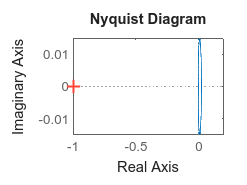

nyquist(GsHs)

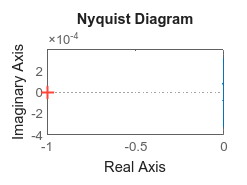

nyquist(GsHs,linspace(6,7,200))

K = 50

K = 50

Gs = K/(s+2)


Gs =
 
   50
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


Hs = 1/((s+4)*(s+6))


Hs =
 
         1
  ---------------
  s^2 + 10 s + 24
 
Continuous-time transfer function.
Model Properties


GsHs = Gs*Hs


GsHs =
 
             50
  ------------------------
  s^3 + 12 s^2 + 44 s + 48
 
Continuous-time transfer function.
Model Properties


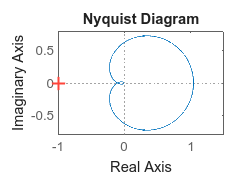


nyquist(GsHs, linspace(0,100,10e4))

Question 4

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties



Gs =  1 / ((s+5)*(s+20)*(s+50))


Gs =
 
               1
  ----------------------------
  s^3 + 75 s^2 + 1350 s + 5000
 
Continuous-time transfer function.
Model Properties


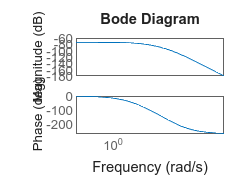


bode(Gs)